# Experiment 2: CNN (Whole Image)

## Clean environment

close all;
clear variables;
clc;
rng(42);

## Set folder path

folder = "C:\Users\u3253992\workspace\computer-vision\assignment_1\u3253992_assignment_1\data\CUB_200_2011_Subset20classes\";

## Load dataset

[trainingImageNames, validationImageNames, testImageNames, classNames, imageClassLabels, boundingBoxes] = loadDataset(folder, true);
numClasses = height(classNames);

## Create datastores

disp('Training set class distribution:');

Training set class distribution:


trainingImageDS = createImageDatastore(trainingImageNames, folder, true, boundingBoxes);

    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  
     017      34  
     018      26  
     019      35  
     020      35  




disp('Validation set class distribution:');

Validation set class distribution:


validationImageDS = createImageDatastore(validationImageNames, folder, true, boundingBoxes);

    Label    Count
    _____    _____

     001       6  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  
     017      12  
     018      10  
     019      12  
     020      12  




disp('Test set class distribution:');

Test set class distribution:


testImageDS = createImageDatastore(testImageNames, folder, true, boundingBoxes);

    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  
     017      11  
     018       9  
     019      12  
     020      12  



## Resize image datastores and combine them with the labels

% targetSize = [128, 128];
targetSize = [224, 224];
% targetSize = [256, 256];
% targetSize = [229, 299];
% targetSize = [384, 384];

trainCDS = resizeCombineDatastore(trainingImageDS, targetSize);
valCDS = resizeCombineDatastore(validationImageDS, targetSize);
testCDS = resizeCombineDatastore(testImageDS, targetSize);

## Show images

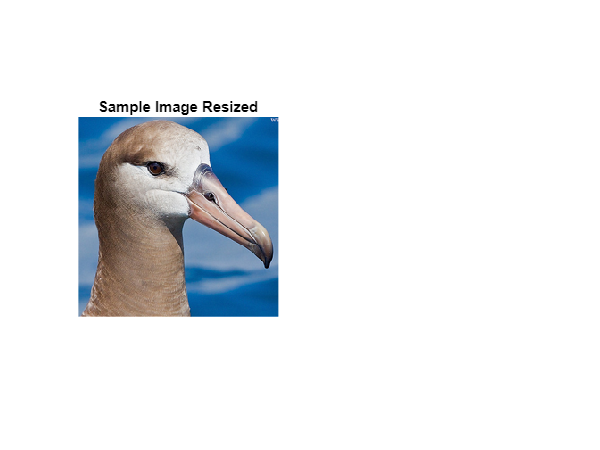

showImage(trainCDS)

## Enables GPU

[device, useGPU] = enableGPU();

✅ GPU found and ready:
  CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589410304 (8.59 GB)
      AvailableMemory: 7441412096 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

## CNN - Convolutional Neural Network

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       14.00% |        6.31% |       3.7519 |      14.7315 |          0.0010 |
|       1 |           2 |       00:00:03 |        4.00% |              |      17.0976 |              |          0.0010 |
|       1 |           3 |       00:00:03 |        4.00% |              |      17.9790 |              |          0.0010 |
|       1 |           4 |       00:00:04 |       12.00% |              |      16.5260 |   

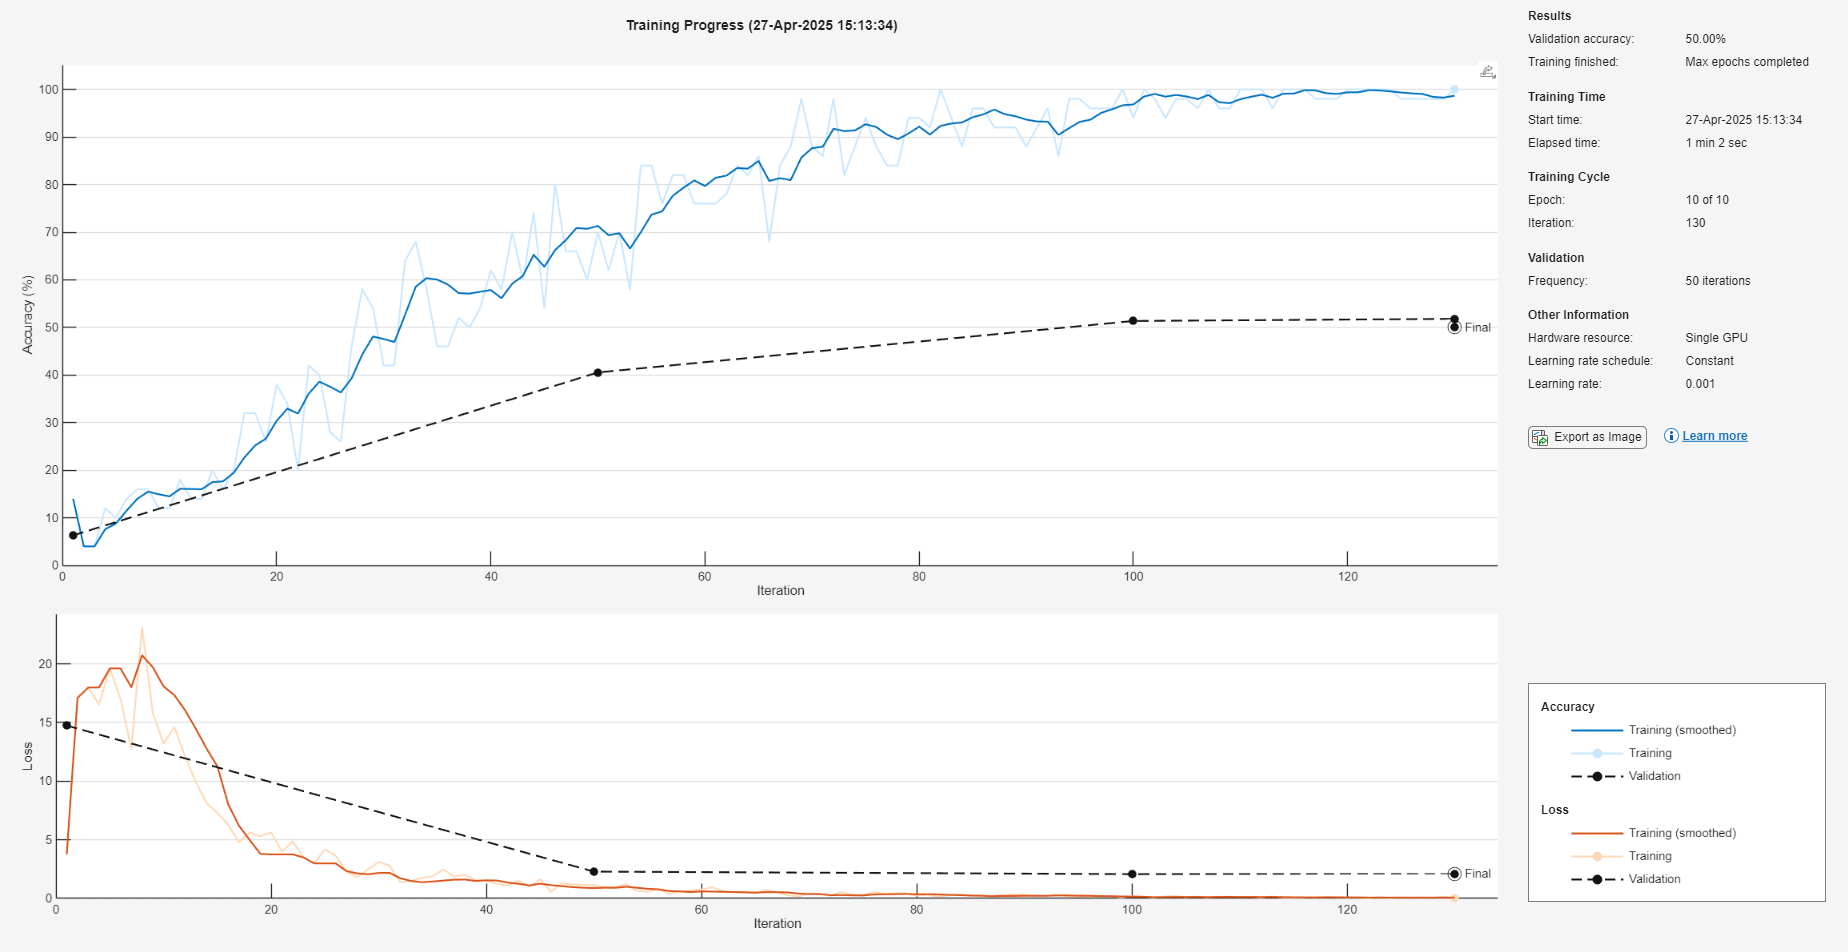

% defines CNN layers
layers = [
    % imageInputLayer([128 128 3])    % This needs to match the image size
    imageInputLayer([224 224 3])
    % imageInputLayer([256 256 3])
    % imageInputLayer([229 229 3])
    % imageInputLayer([384 384 3])

    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 128, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    fullyConnectedLayer(20)
    softmaxLayer
    classificationLayer];

% sets training options
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MiniBatchSize', 50, ...
    'MaxEpochs', 10, ...
    'Verbose', true, ...
    'Shuffle', 'every-epoch', ...
    'VerboseFrequency', 1, ...
    'ValidationData', valCDS, ...
    'Plots','training-progress');

% model training
simpleCNN = trainNetwork(trainCDS, layers, options);

## Evaluate the model

[trainAccuracy, trainPredictions] = evaluateClassifier(simpleCNN, trainCDS, trainingImageDS.Labels, true);
[valAccuracy, valPredictions] = evaluateClassifier(simpleCNN, valCDS, validationImageDS.Labels, true);
[accuracy, predictions] = evaluateClassifier(simpleCNN, testCDS, testImageDS.Labels, true);


disp("Train Accuracy = "+string(round(trainAccuracy*100, 1)))

Train Accuracy = 99.4


disp("Validation Accuracy = "+string(round(valAccuracy*100, 1)))

Validation Accuracy = 50


disp("Test Accuracy = "+string(round(accuracy*100, 1)))

Test Accuracy = 55.9


## Plot confusion matrix

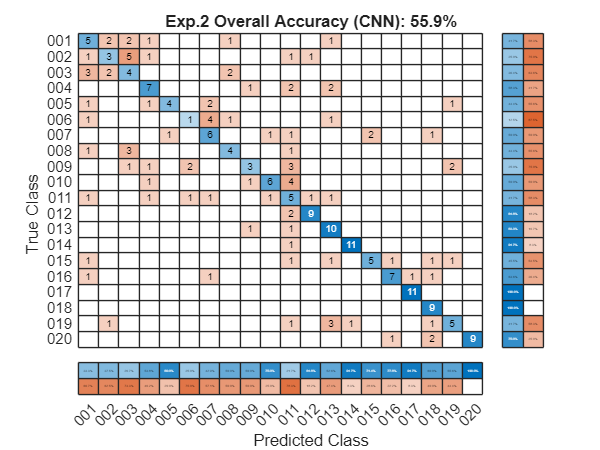

Classwise Recognition Rates:
   41.7000
   25.0000
   36.4000
   58.3000
   44.4000
   12.5000
   50.0000
   44.4000
   25.0000
   50.0000
   41.7000
   81.8000
   83.3000
   91.7000
   45.5000
   63.6000
  100.0000
  100.0000
   41.7000
   75.0000



plotConfusionMatrix(testImageDS.Labels, predictions, "Exp.2 Overall Accuracy (CNN): " + string(round(accuracy*100, 1)) + "%");